clc; clear; close all;

## INTRODUCTION TO STOCHASTICITY

% Electrical engineers often use MATLAB to simulate random process, and the
% reason that it is so popular is that a lot of problems in EE are
% stochastic problems. What happens when there's random noise in a channel,
% what is the probability of corrupting a signal to the point that it
% cannot be recovered? 

% Today, we are going to explore the idea of randomness with case studies.
% We are first going to show simple examples of stochastic processes, and
% will conclude with a more elaborate exploration of stochasticity in
% communication channels

## EXAMPLE 1 : MONTY HALL

The classic monty hall problem -- do you switch the door or not. The correct answer is you always switch. But why?? Let's find out

% Let's do a simulation to experimentally see the results, let's say there
% are two contestants, the first contestant never switches, the second
% contestant switches. 

% There are different ways to do it. Let's assume that the prize is
% always behind door 3 and we choose at random which door the contestant
% chooses.

% If contestant 1 picks 3, then the contestant wins. For contestant 2, if
% the contestant chooses 3 then we choose one of the two other doors at
% random to show. If contestant 2 chose door 1 or 2, we show the
% contestant the other empty door.

N = 5e5;
choose_door = unidrnd(3,1,N);
result = zeros(2,N);
result(1, choose_door == 3) = 1;

% Inefficient but for readability. It's clear that contestant 2 has a 2/3
% success rate
for i = 1:N
    if choose_door(i) == 3
        choose_door(i) = unidrnd(2,1);
    else
        choose_door(i) = 3;
    end
end

result(2, choose_door == 3) = 1;

% take the running mean
win_rate = cumsum(result, 2);
x = 1:1:N;
win_rate = win_rate ./ [x;x];

## Plotting the results of example 1

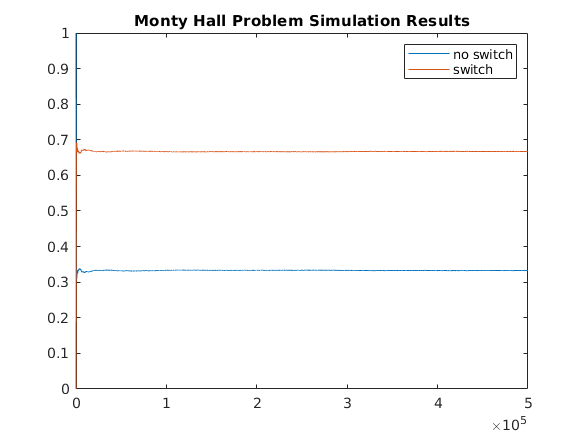

figure;
plot(x, win_rate(1,:), 'DisplayName','no switch');
hold on;
plot(x, win_rate(2,:), 'DisplayName', 'switch');
legend('show');
title('Monty Hall Problem Simulation Results')
hold off;

## EXAMPLE 2 : CASINO

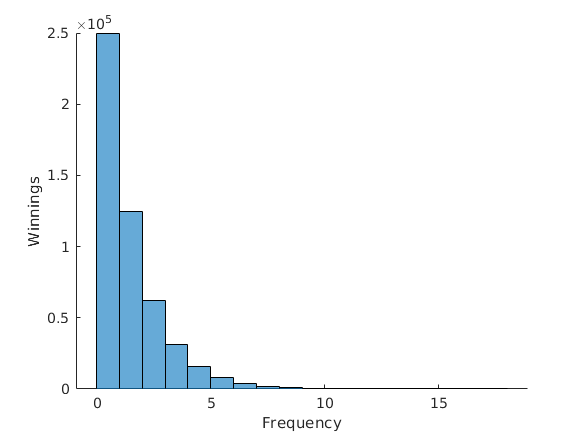

% A casino offers a game in which a fair coin is tossed repeatedly until
% the first heads comes up, for a total of k+1 tosses. The casino will pay
% out k dollars

% Let's see how much money you are going to get if you play the game
N = 5e5;
num_tosses = zeros(1,N);
for i = 1:N
   res = randi([0,1]);
   while (res ~= 0)
      num_tosses(i) = num_tosses(i) + 1;
      res = randi([0,1]);
   end
end

figure;
hold on;
histogram(num_tosses, unique(num_tosses));
xlabel('Frequency');
ylabel('Winnings');
hold off;

## Radar/Signal Detection Example

N = 10000;
i = 1:N;
rdm = rand(1,N);
X = rdm > 0.5;     % Signal: 0 or 1 equiprobable
N = randn(1,N);    % Noise: standard normal

Y = X + N;         % Recieved

% For each observation, either the sample comes from N(0,1) or N(1,1)

% To guess if the true signal for each observation, x_i is 0 or 1 we 
% compute P[true = 0 | x_i] and P[true = 1 | x_i] and choose the larger
% one.

% By Bayes' Law, 
%                     P[x_i | true = S]*P[true = S]
% P[true = S | x_i] = ----------------------------- , S = 0,1
%                                 P[x_i]

% Since P[x_i] is common to both P[true = 0 | x_i] and P[true = 1 | x_i],
% we only have to maximize the numerator. Also since 
% P[true = 0] = P[true = 1], we need to maximize P[x_i | true = S], S = 0,1

## Showing the decision boundary visually

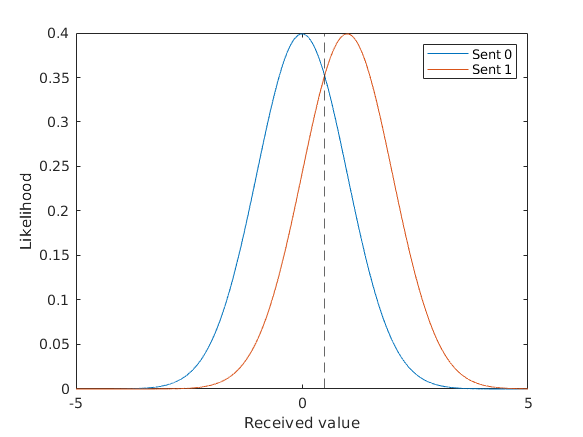

x = -5:0.001:5;
figure;
plot(x,[normpdf(x,0,1); normpdf(x,1,1)]);
xline(0.5,'--');

legend(["Sent 0", "Sent 1"]);
xlabel('Received value');
ylabel('Likelihood');

## Modeling the distribution boundary

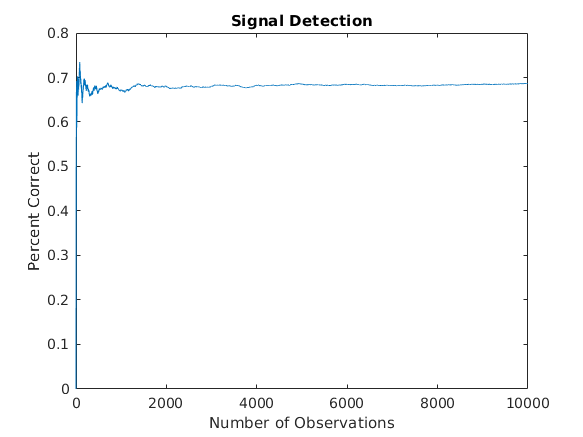

prob0 = normpdf(Y,0,1);
prob1 = normpdf(Y,1,1);

decision = prob1 > prob0;
result = decision == X;

figure;
plot(i,cumsum(result)./i);
xlabel("Number of Observations");
ylabel("Percent Correct");
title("Signal Detection");

What happens if the prior probabilities are not equal?

If the priors are known, then we can multiply them to the probabilities we used earlier according to Bayes' Law. This technique is called MAP (Maximum a posteriori) estimation.

But if the priors are NOT known, then we can assume equiprobable and use the same technique as before. This technique is called ML (Maximum likelihood) estimation. Clearly this performs worse than MAP if the priors are not equal, i.e., the equiprobable assumption is false.

P0 = 0.8;
X = rdm > P0;    % Now the signal is 1 with probability 0.2

Y = X + N;

## Graphing this new problem

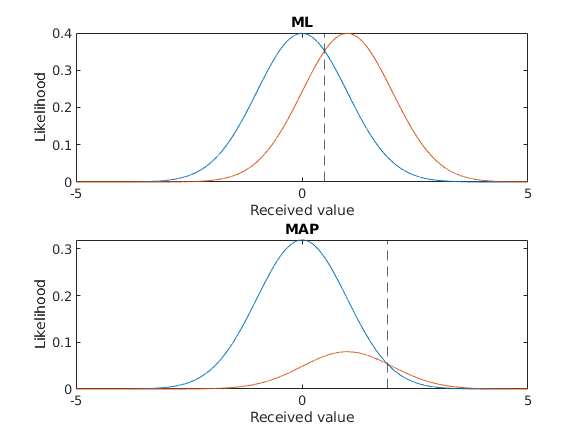

figure;
subplot(211);
plot(x,[normpdf(x,0,1); normpdf(x,1,1)]);
xline(0.5,'--');
title("ML");
xlabel('Received value');
ylabel('Likelihood');

subplot(212);
plot(x,[normpdf(x,0,1)*P0; normpdf(x,1,1)*(1 - P0)]);
xline(0.5 + log(P0/(1-P0)),'--');
title("MAP");
xlabel('Received value');
ylabel('Likelihood');

## MAP decision rule

Now we include the priors

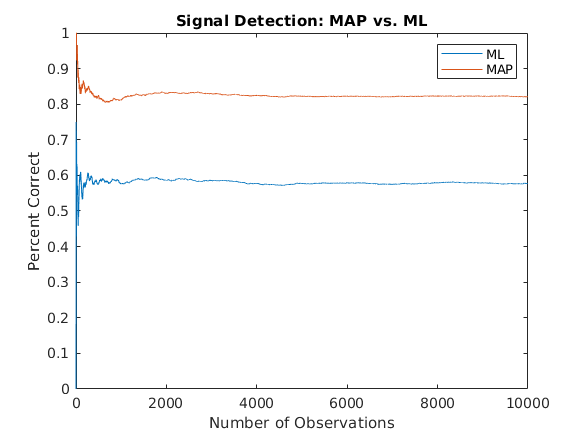

prob0MAP = normpdf(Y,0,1)*P0;
prob1MAP = normpdf(Y,1,1)*(1 - P0);

decisionMAP = prob1MAP > prob0MAP;

resultML = decision == X;       % previous example was ML
resultMAP = decisionMAP == X;   % current MAP estimate

figure;
plot(i,[cumsum(resultML)./i; cumsum(resultMAP)./i]);
xlabel("Number of Observations");
ylabel("Percent Correct");
title("Signal Detection: MAP vs. ML");
legend("ML","MAP");